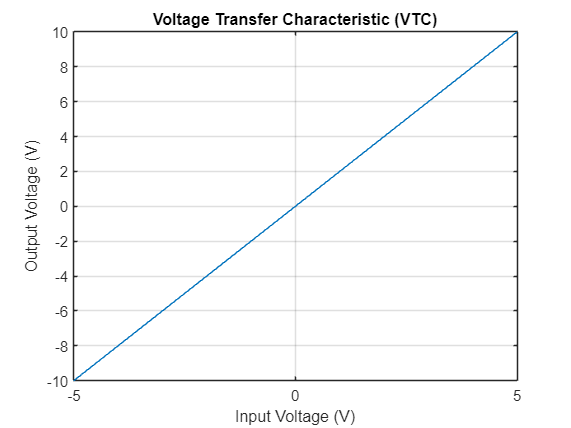

% Constants and parameters
Vin = linspace(-5, 5, 1000); % Input voltage range
R1 = 10e3; % Resistor R1 value
R2 = 10e3; % Resistor R2 value
Vcc = 10; % Supply voltage
Voffset = 0.5; % Input offset voltage
Vos_max = 0.1; % Maximum input offset voltage

% 1. Voltage transfer characteristic (VTC)
Vout = (1 + R2/R1) * Vin; % Ideal VTC
figure;
plot(Vin, Vout);
xlabel('Input Voltage (V)');
ylabel('Output Voltage (V)');
title('Voltage Transfer Characteristic (VTC)');
grid on;

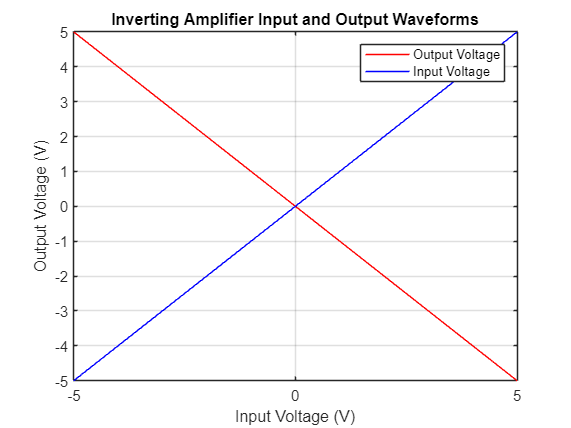


% 2. Input and output waveforms for an inverting amplifier configuration
Vin_inverting = linspace(-5, 5, 1000); % Input voltage range for inverting amplifier
Vout_inverting = -R2/R1 * Vin_inverting; % Output voltage for inverting amplifier
figure;
plot(Vin_inverting, Vout_inverting, 'r');
hold on;
plot(Vin_inverting, Vin_inverting, 'b');
xlabel('Input Voltage (V)');
ylabel('Output Voltage (V)');
title('Inverting Amplifier Input and Output Waveforms');
legend('Output Voltage', 'Input Voltage');
grid on;

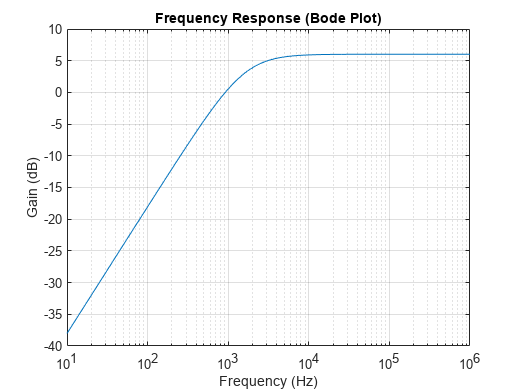


% 3. Frequency response (Bode plot)
f = logspace(1, 6, 1000); % Frequency range from 10 to 10^6 Hz
A = 1 + R2/R1; % DC gain
f_cutoff = 1/(2*pi*R1*10e-9); % Cutoff frequency (10nF capacitor)
H = @(f) A ./ sqrt(1 + (f_cutoff ./ f).^2); % Transfer function
figure;
semilogx(f, 20*log10(H(f)));
xlabel('Frequency (Hz)');
ylabel('Gain (dB)');
title('Frequency Response (Bode Plot)');
grid on;

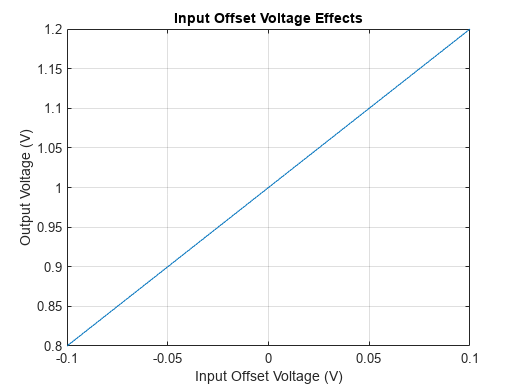


% 4. Input offset voltage effects
Vin_offset = linspace(-Vos_max, Vos_max, 1000); % Input offset voltage range
Vout_offset = (1 + R2/R1) * (Vin_offset + Voffset); % Output voltage with offset
figure;
plot(Vin_offset, Vout_offset);
xlabel('Input Offset Voltage (V)');
ylabel('Output Voltage (V)');
title('Input Offset Voltage Effects');
grid on;